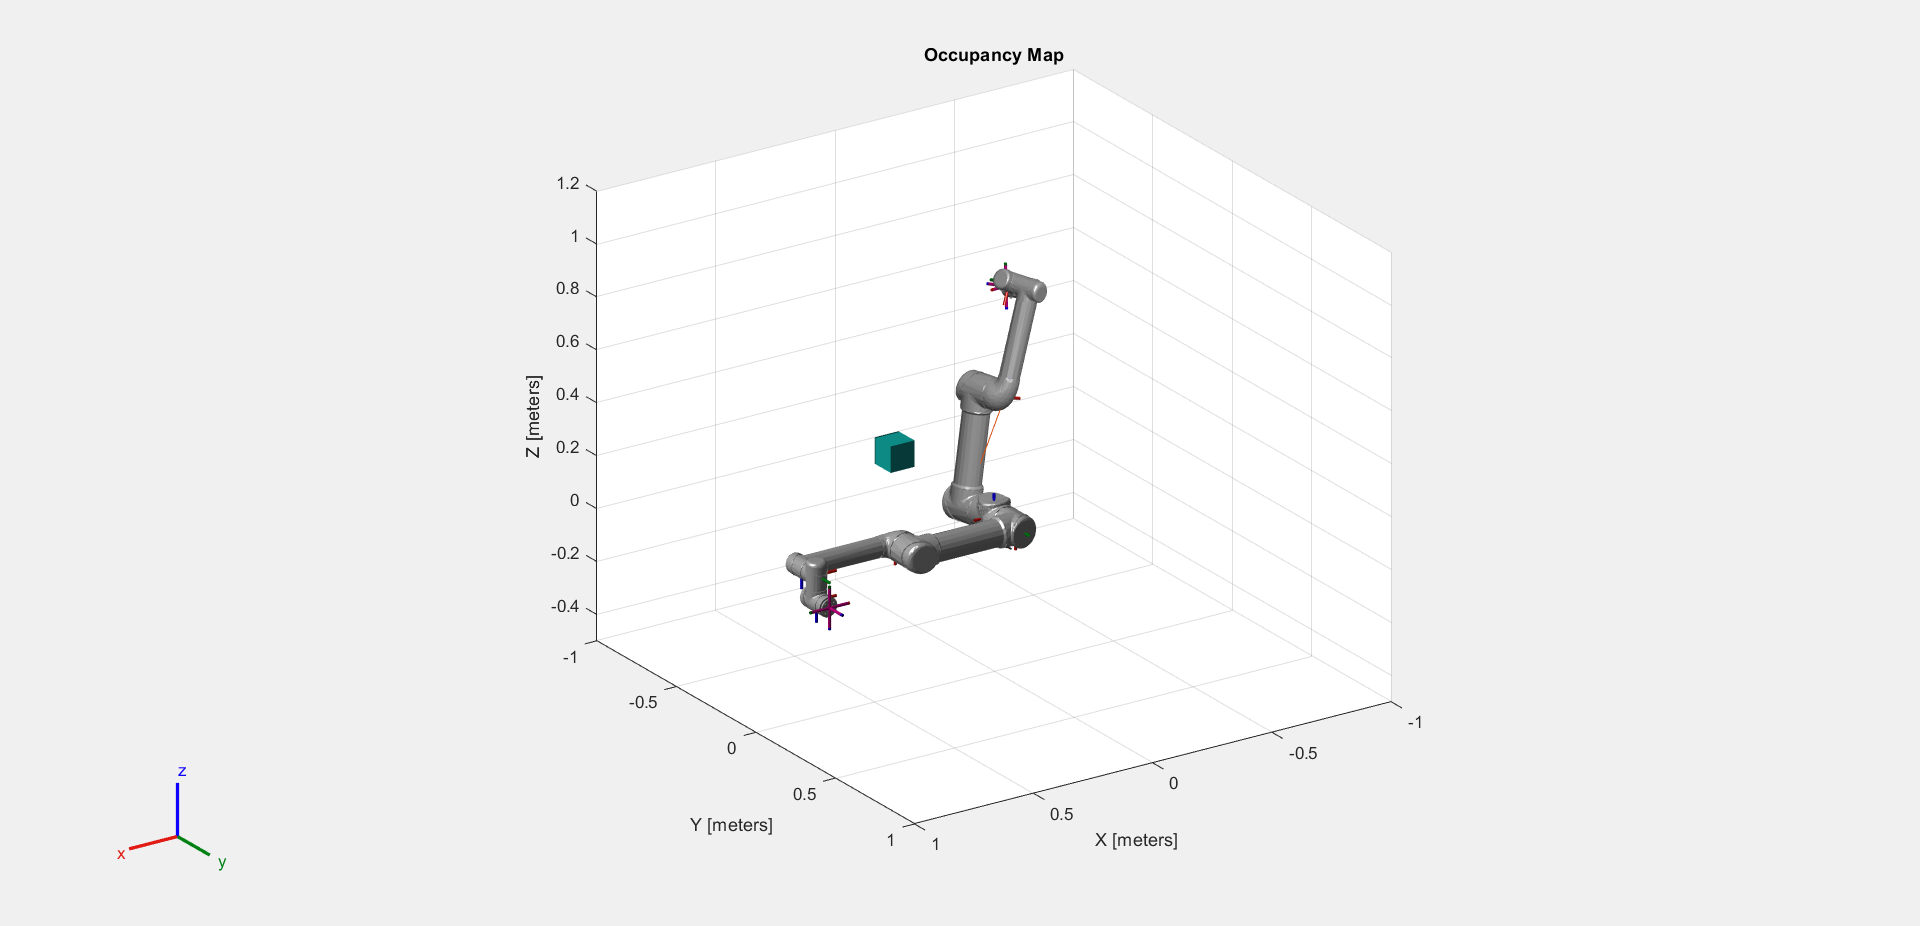

% Cargar el modelo del UR5
robot = loadrobot("universalUR5", "DataFormat", "row");

map = occupancyMap3D(10);
map.setOccupancy([0.4 0.0 0.4],1);


show(map);
hold on
show(robot);
axis("equal")
xlim([-1,1.0])
ylim([-1,1.0])
zlim([-0.5,1.2])

startConfig = [2.2131,-1.3950,0.1618,0.2053,-0.1624,1.1684];
goalconfig = startConfig;
goalconfig(1) = 3.4;

planner = manipulatorRRT(robot,{},Map=map);
planner.ValidationDistance=0.1;
planner.MaxConnectionDistance=0.2;
planner.SkippedSelfCollisions="parent";

plannedpath = plan(planner,startConfig,goalconfig);
interpoalatedpath = interpolate(planner,plannedpath);

rc=rateControl(10);
view([pi/3,pi/2,pi/4]);
for i = 1:size(interpoalatedpath,1)
    show(robot,interpoalatedpath(i,:),FastUpdate=true,PreservePlot=false);
    waitfor(rc);
end